Limpar 

close all
clear
clc

# Analise CC para emisro comum com polarização por divisor de tensão

Figura 1- Circuito base

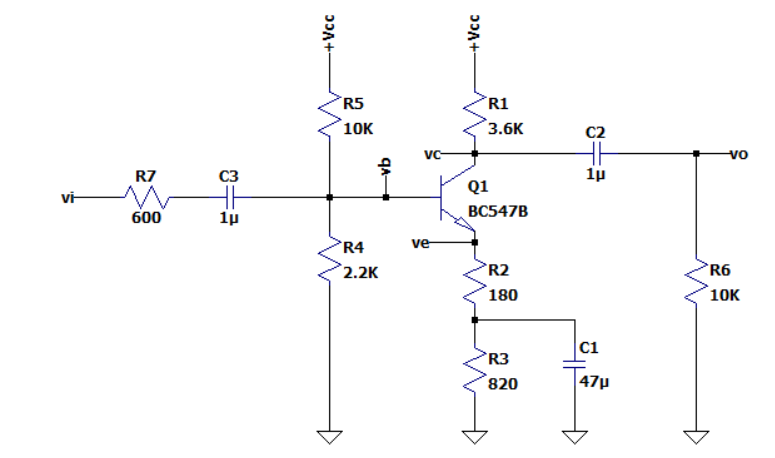

## ** Calc Analise CC (DC)**

Figura 2- Circuito para analise CC

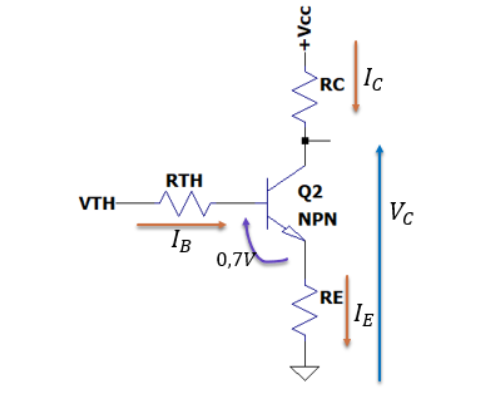

### Valores dos componentes:

R5 = 10e+3;%%Rth
R4 =2.2e+3;%%Rth
RE = 1e+3;%% R2+R3
Vcc = 10;%%Variavel de entrada
B = 290; % Beta para o calc
Vbe = 0.7; 
Vce = 5; %data sheet


### Equivalentes de TH

Vth = (R4/(R5+R4))*Vcc

Vb = 1.8033

Rth = ((1/R5)+(1/R4))^-1

Ve = 1.0965

### Correntes

Ib = (Vth-Vbe)/(Rth+RE*(B+1))

Vc = 6.0965

Ic = (B+1)*Ib
Ie = Ic

### Tensões CC

Vb = Vth
Ve = RE*Ie
Vc = Vce+Ve


## **Calc Analise CA (AC)**

Figura 3- Circuito para analise CA

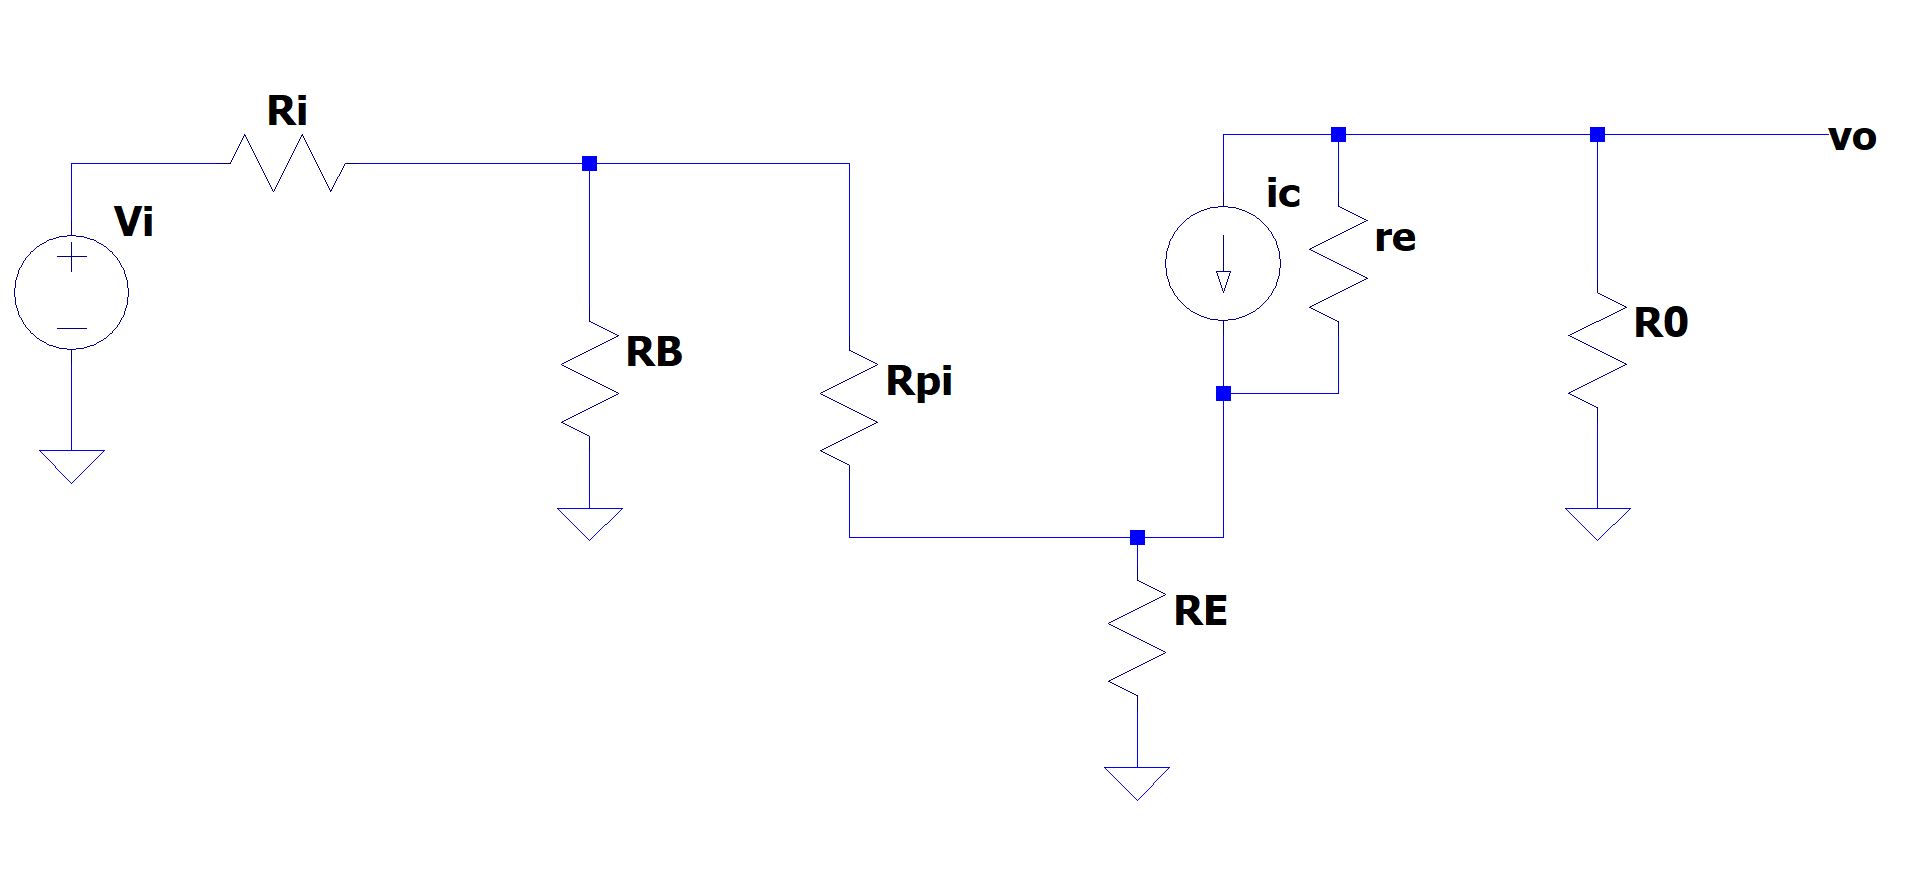

### Valores dos componentes 

*Obs.: todos os valores de componentes possuem a variavel com nome correspondente ao circuito apresentado na figura 1.

Ri = 600; %valor de entrada da figura 1

R0 = 2.6471e+03

RL = 10e+3;%valor de entrada da figura 1
RC = 3.6e+3;%valor de entrada da figura 1
RB = Rth; %calculado

vi = 0.0100

R0 = ((1/RL)+(1/RC))^-1%calculado R0
RE = 180; %valor de entrada da figura 1  R2

re = 20.0641

VT = 22e-3;%% Tensão termica dado no datasheet VT = (K*T)/q

rpi = 5.8387e+03

vi = 10e-3

### calculo do re e rpi:

re = VT/Ie

Zb = 5.8219e+04

rpi = (B+1)*re

vb = 0.0074

### **Calculo para CA**

Zb = (B+1)*(RE+re)

ib = 1.2789e-07

vb = (((1/RB)+(1/Zb))^-1/(Ri+((1/RB)+(1/Zb))^-1))*vi

ic = 3.7089e-05

ib = vb/Zb

ie = -3.7217e-05

ic = B*ib

Av = -9.8178

ie = (-vb+rpi*ib)/RE

vo = -0.0982

Av = -B*((R0)/(Ri+((Ri/RB)+1)*(B+1)*(RE+re)))

Z0 = 2.6471e+03

vo = Av*vi

ve = -0.0067

Z0 = R0

vc = -0.0982

ve = RE*ie

Zi = 1.9778e+03

vc=vo
Zi = Ri+((1/RB)+(1/rpi))^-1

Valores obtidos na simulação

svb = 1.8037758 - 1.7963748

svb = 0.0074

svc = 5.949987 - 5.8546929

svc = 0.0953

sve = 1.1618357 - 1.1553028

sve = 0.0065


sib = 3.9556925e-6 - 3.8285366e-6

sib = 1.2716e-07

sic = 1.1876222e-3 - 1.1514742e-3

sic = 3.6148e-05

sie = -1.1194918e-3 + 1.1553027e-3

sie = 3.5811e-05

sAv = 95.250003e-3/9.9808408e-3

sAv = 9.5433

Calculando saturação e corte maximo

Vct = Ve+ve

Vct = 1.0898

visatura = (vc-0.2)/ve

visatura = 44.5101

if (vi>= visatura)
    fprintf 'saturou';
else 
    fprintf 'Continue tentando';
end

Continue tentando

vicorte = -Ib/ib

vicorte = -29.4617

if (vi<= vicorte)
    fprintf 'esta em corte';
else
    fprintf 'Continue tentando';
end

Continue tentando